ASP

Felber Peter

Example 1

Special Signals

Special Signals play a crucial role in DSP, they are used to determine the impulse response and support the representation of signals. In this very first task implement the delta-function and the step function as standalone functions

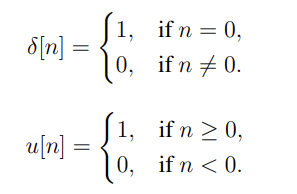

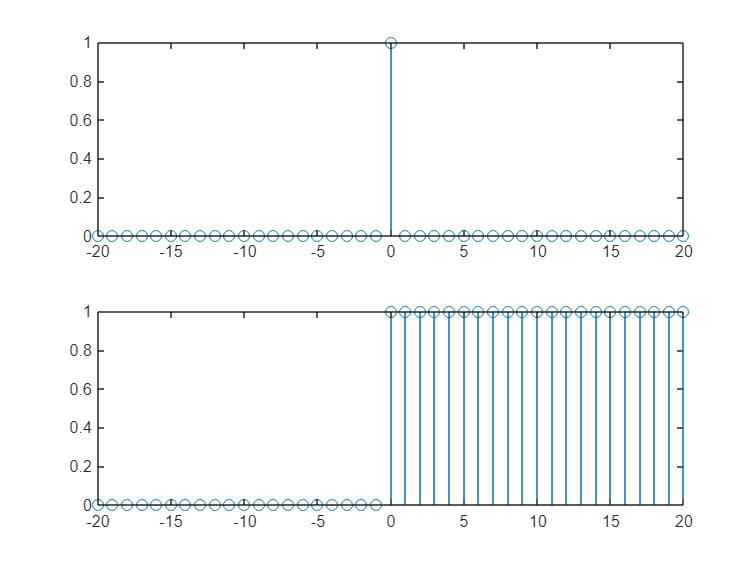

figure
vn = -20:1:20;
vDelta = Felber.vDeltaFun(vn);
subplot(2,1,1)
stem(vn,vDelta)

vStep = Felber .vStepFun(vn);
subplot(2,1,2)
stem(vn,vStep)

After your implementation test your functions and create and stem the following signals:

(a) δ[n + 1], δ[n − 3] and δ[n + 6]

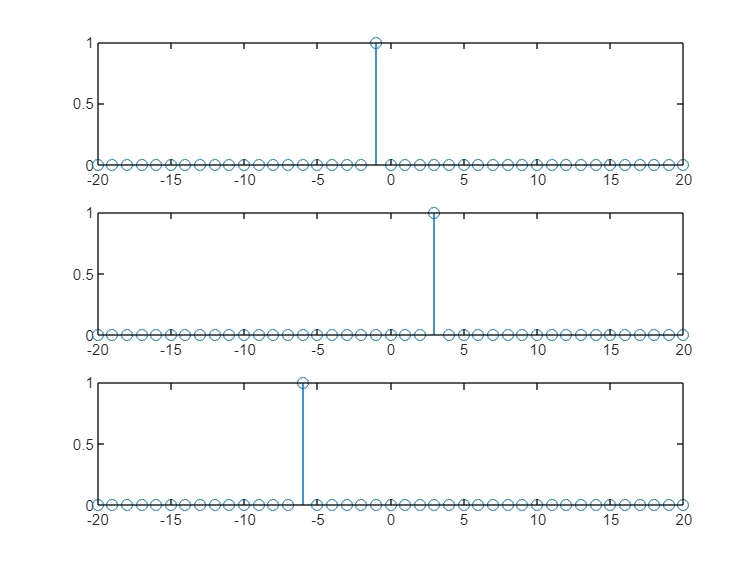

a1Delta = Felber.vDeltaFun(vn+1);
a2Delta = Felber.vDeltaFun(vn-3);
a3Delta = Felber.vDeltaFun(vn+6);

figure
subplot(3,1,1)
stem(vn,a1Delta)
subplot(3,1,2)
stem(vn,a2Delta)
subplot(3,1,3)
stem(vn,a3Delta)

(b) u[n + 5], u[n] and u[n − 3]

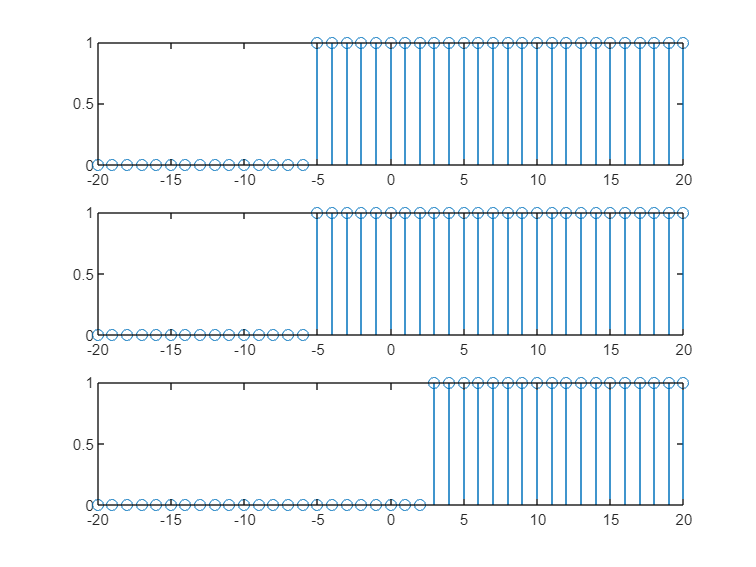

b1Step = Felber.vStepFun(vn+5);
b2Step = Felber.vStepFun(vn+5);
b3Step = Felber.vStepFun(vn-3);

figure
subplot(3,1,1)
stem(vn,b1Step)
subplot(3,1,2)
stem(vn,b2Step)
subplot(3,1,3)
stem(vn,b3Step)

(c) 3δ[n + 1] + n^2 (u[n + 5] − u[n + 4]) + 10(0.5)^n 

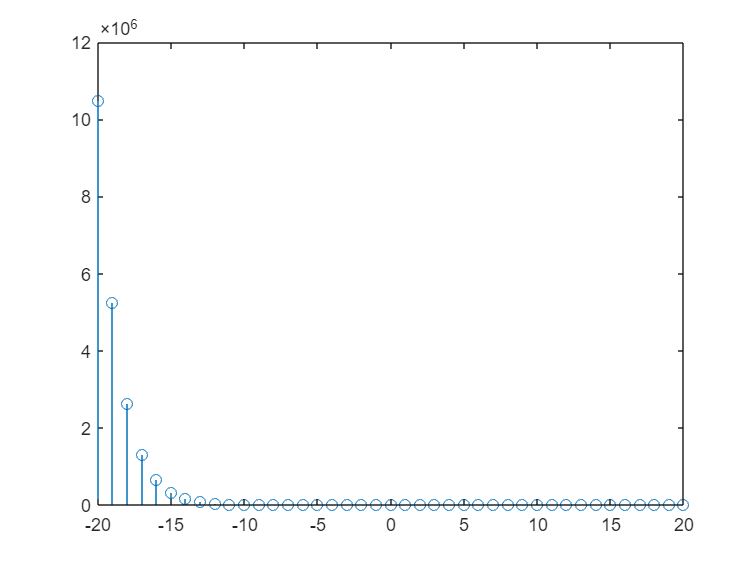

c1DeltaStep = 3 * (Felber.vDeltaFun(vn+1)) + power(vn,2) .* (Felber.vStepFun(vn+5)-Felber.vStepFun(vn+4)) + 10*power(0.5,vn);
figure
stem(vn,c1DeltaStep)

for −20 ≤ n ≤ 20 

Example 2

Signal modification 

Investigate in the MATLAB functions fliplr, circshift using MATLAB help 

Modify the following signal: 

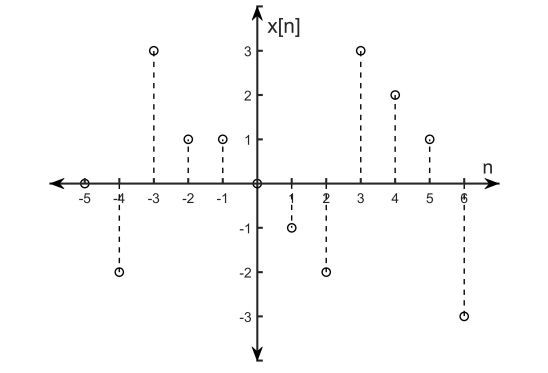

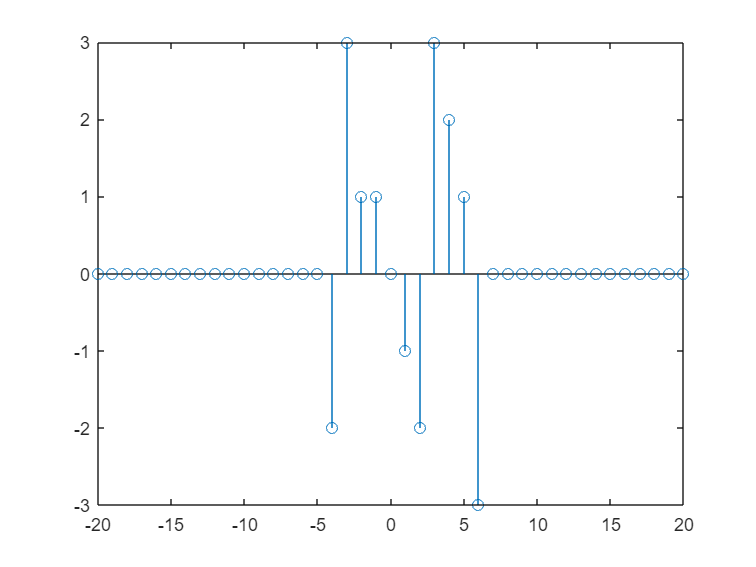


Signal2 = -2*Felber.vDeltaFun(vn+4)+3*Felber.vDeltaFun(vn+3)+Felber.vDeltaFun(vn+2)+Felber.vDeltaFun(vn+1)-1*Felber.vDeltaFun(vn-1)-2*Felber.vDeltaFun(vn-2)+3*Felber.vDeltaFun(vn-3)+2*Felber.vDeltaFun(vn-4)+Felber.vDeltaFun(vn-5)-3*Felber.vDeltaFun(vn-6);
stem(vn,Signal2)

After your implementation test your functions and create and stem the following signals

(a) x[3n + 5] 

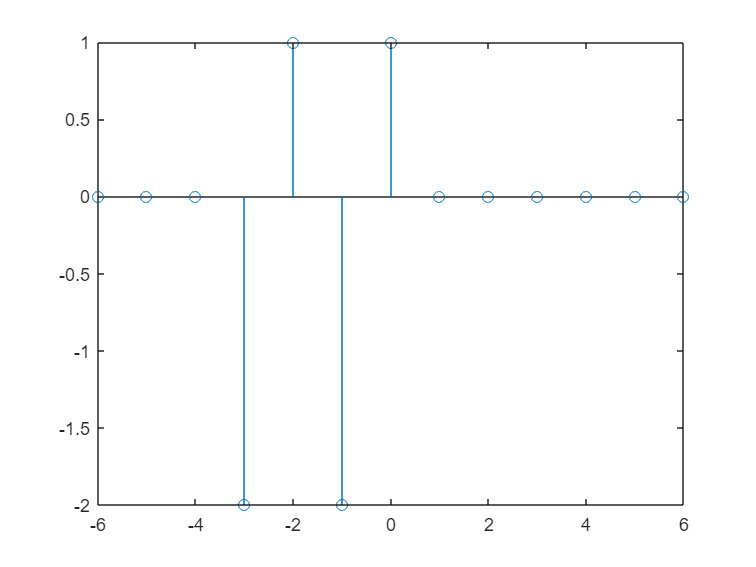

a2 = circshift(Signal2,-5) ;
va2 = vn(3:3:length(vn));
a2 = a2(3:3:length(vn));
stem(va2/3,a2)

(b) x[−5n + 4] 

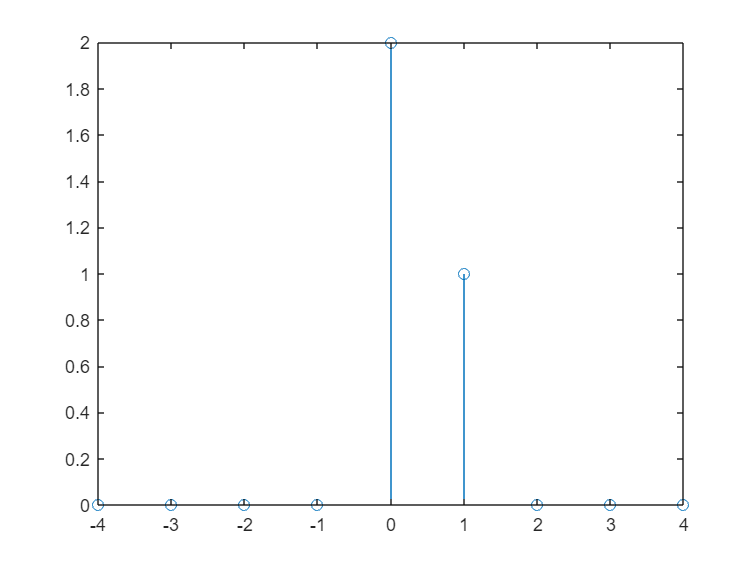

b2 = circshift(Signal2,-4) ;
b2 = fliplr(b2);
vb2 = vn(1:5:length(vn));
b2 = b2(1:5:length(vn));
stem(vb2/5,b2)

(c) x[n^2 ] 

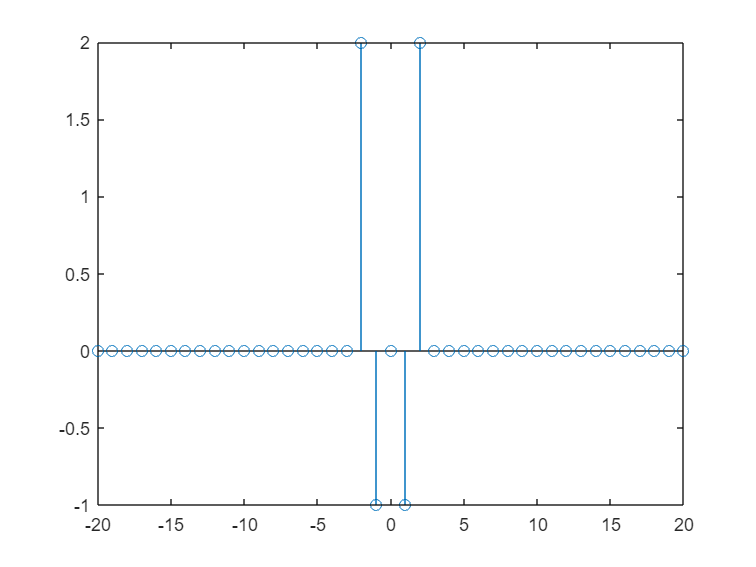

c2 =Mayer.scaleFunc(Signal2,vn,vn.^2) ;
stem(vn,c2)

(d) y[n] = x[n] − u[n − 1]x[n − 2] 

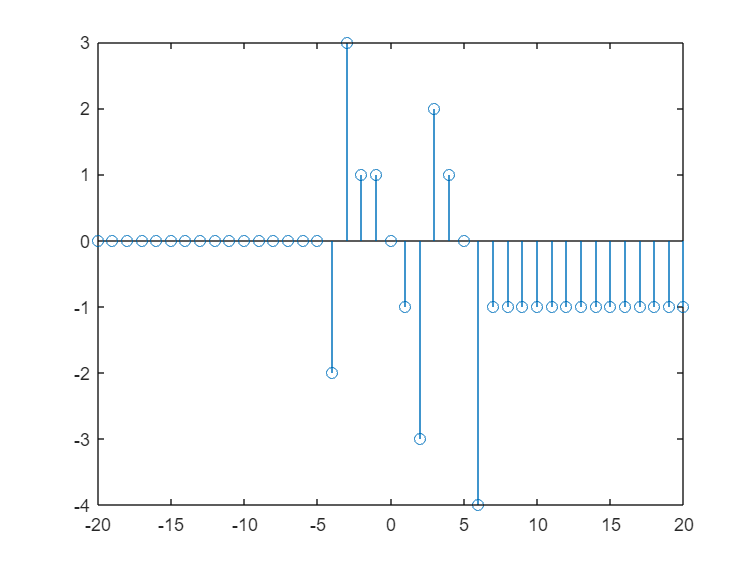

d2 = Signal2-Felber.vStepFun(vn-1).*Felber.vStepFun(vn-2);
stem(vn,d2)

Example 3: 

Representation of DT Signals

Investigate in the MATLAB functions imag, real, fliplr, circshift using MATLAB help 

Use the signal x[n] = (−0.2 + j0.3)^n sin(π/4 n)(u[n + 3] − u[n − 5]) for the following tasks. 

Signal3 = (-0.2+1j*0.3).^vn .*sin(pi/4 * vn).*(Felber.vStepFun(vn+3)-Felber.vStepFun(vn-5));

(a) Write a function [vxe,vxo]=analyzeSignal(vn,vx), which calculates the even x_e[n] and the odd x_o[n] part of the signal x[n].

[vxe, vxo] = Felber.analyzeSignal(vn, Signal3);

figure;

% Plot für das ursprüngliche Signal
subplot(3,1,1);
stem(vn, real(Signal3));
title('Original Signal: x[n]');
xlabel('n');
ylabel('Amplitude');
xlim([-5, 5]);  
ylim([-16, 4]); 

% Plot für den geraden Teil
subplot(3,1,2);
stem(vn, vxe);

title('Even Part: x_e[n]');
xlabel('n');
ylabel('Amplitude');
xlim([-5, 5]);   
ylim([-16, 4]);  

% Plot für den ungeraden Teil
subplot(3,1,3);
stem(vn, vxo);

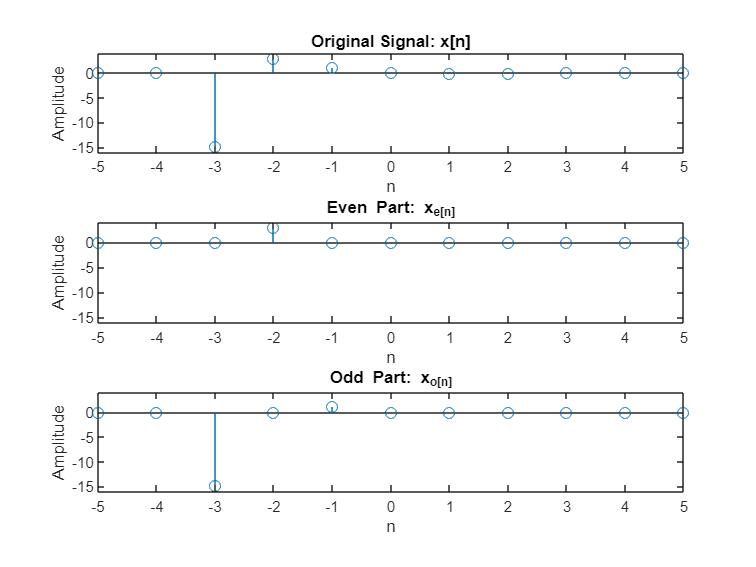

title('Odd Part: x_o[n]');
xlabel('n');
ylabel('Amplitude');
xlim([-5, 5]);  
ylim([-16, 4]); 

(b) Plot the real part and the imaginary part of xe[n]. Does the result agree with your expectations?

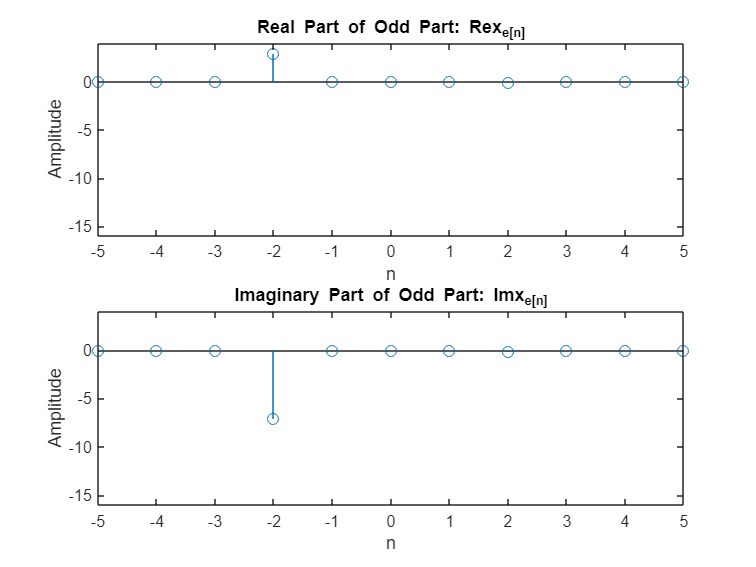

% Plot für den realen Teil von xe[n]
figure;
subplot(2,1,1);
stem(vn, real(vxe));
title('Real Part of Odd Part: Re{x_e[n]}');
xlabel('n');
ylabel('Amplitude');
xlim([-5, 5]); 
ylim([-16, 4]); 

% Plot für den imaginären Teil von xo[n]
subplot(2,1,2);
stem(vn, imag(vxe));
title('Imaginary Part of Odd Part: Im{x_e[n]}');
xlabel('n');
ylabel('Amplitude');
xlim([-5, 5]);
ylim([-16, 4]); 

(c) Plot the real part and the imaginary part of xo[n]. Does the result agree with your expectations?

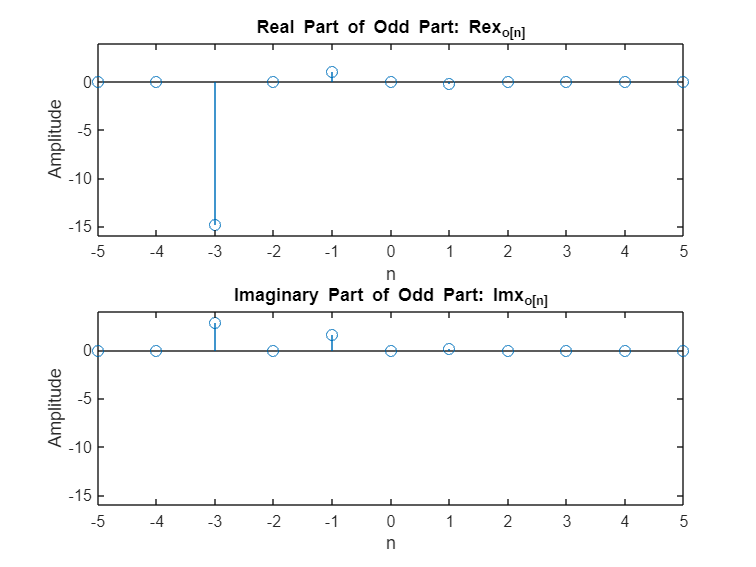

% Plot für den realen Teil von xo[n]
figure;
subplot(2,1,1);
stem(vn, real(vxo));
title('Real Part of Odd Part: Re{x_o[n]}');
xlabel('n');
ylabel('Amplitude');
xlim([-5, 5]); 
ylim([-16, 4]); 

% Plot für den imaginären Teil von xo[n]
subplot(2,1,2);
stem(vn, imag(vxo));
title('Imaginary Part of Odd Part: Im{x_o[n]}');
xlabel('n');
ylabel('Amplitude');
xlim([-5, 5]);
ylim([-16, 4]); 

(d) Apply the function analyzeSignal(vn,vx) to the signals xr[n] = ℜ(x[n]) and jxi [n] = jℑ(x[n])

% Signal xr[n]
xr = real(Signal3);

% Signal jxi[n]
jxi = 1i * imag(Signal3);

% Anwendung der Funktion auf xr[n]
[vxe_xr, vxo_xr] = Felber.analyzeSignal(vn, xr);

% Anwendung der Funktion auf jxi[n]
[vxe_jxi, vxo_jxi] = Felber.analyzeSignal(vn, jxi);

(e) Plot the signals xr,e[n] and xr,o[n]. Do the results agree with (b) and (c)? Why or why not?

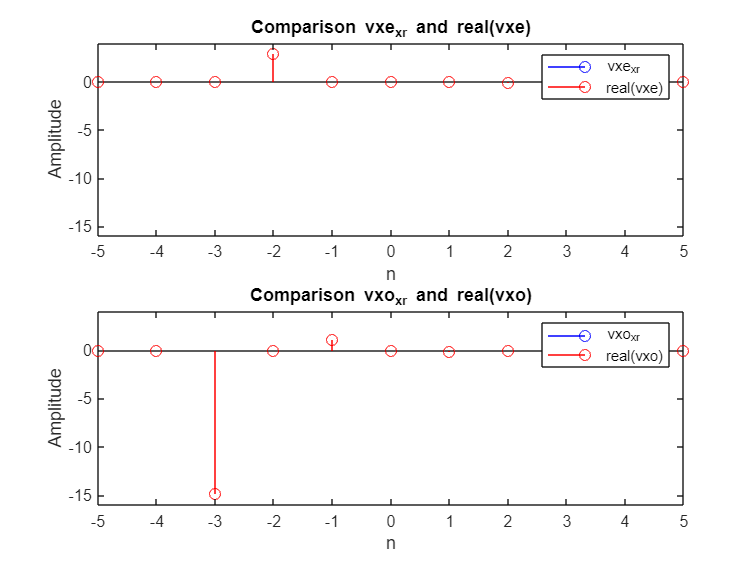

% Vergleich von vxe_xr und real(vxe)
figure;
subplot(2,1,1);
stem(vn, vxe_xr, 'b', 'DisplayName', 'vxe_xr');
hold on;
stem(vn, real(vxe), 'r', 'DisplayName', 'real(vxe)');
hold off;
title('Comparison vxe_xr and real(vxe)');
xlabel('n');
ylabel('Amplitude');
xlim([-5, 5]); 
ylim([-16, 4]); 
legend;

% Vergleich von vxo_xr und real(vxo)
subplot(2,1,2);
stem(vn, vxo_xr, 'b', 'DisplayName', 'vxo_xr');
hold on;
stem(vn, real(vxo), 'r', 'DisplayName', 'real(vxo)');
hold off;
title('Comparison vxo_xr and real(vxo)');
xlabel('n');
ylabel('Amplitude');
xlim([-5, 5]); 
ylim([-16, 4]); 
legend;

(f) Plot the signals xi,e[n] and xi,o[n]. Do the results agree with (b) and (c)? Why or why not? 

% Vergleich von vxe_jxi und imag(vxe)
figure;
subplot(2,1,1);
stem(vn, vxe_jxi, 'b', 'DisplayName', 'vxe_jxi');

hold on;
stem(vn, imag(vxe), 'r', 'DisplayName', 'imag(vxe)');
hold off;
title('Comparison vxe_xr and real(vxe)');
xlabel('n');
ylabel('Amplitude');
xlim([-5, 5]); 
ylim([-16, 4]); 
legend;

% Vergleich von vxo_jxi und imag(vxo)
subplot(2,1,2);
stem(vn, vxo_jxi, 'b', 'DisplayName', 'vxo_jxi');

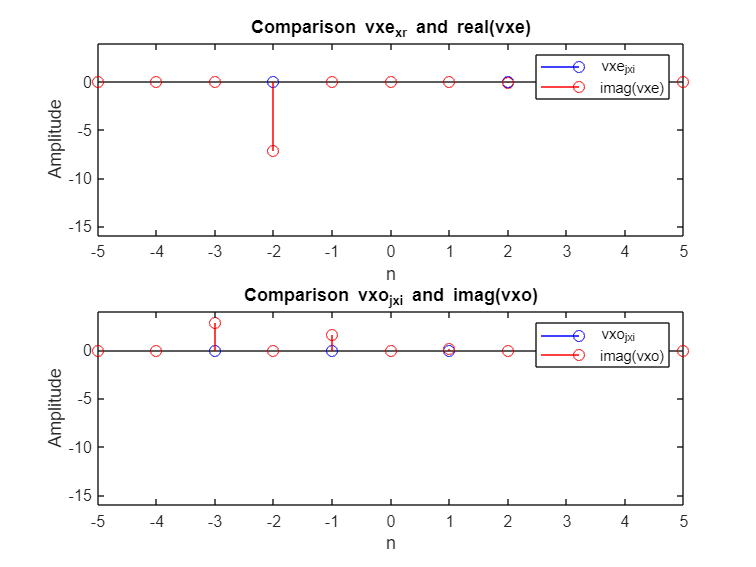

hold on;
stem(vn, imag(vxo), 'r', 'DisplayName', 'imag(vxo)');
hold off;
title('Comparison vxo_jxi and imag(vxo)');
xlabel('n');
ylabel('Amplitude');
xlim([-5, 5]); 
ylim([-16, 4]); 
legend;

When plotting the real part of a complex number, only the real component is plotted. 

However, when applying `imag()`, the imaginary part is isolated and treated as a real number, allowing it to be plotted separately.

Example 4: 

Convolution

Investigate in the MATLAB functions audioread, sound using MATLAB help

For a given input signal x[n] = [1, 5, −1, 6, 3] and a system output signal y[n] = 3x[n] − 4x[n − 2] + 6x[n − 4] compute the convolution of two vectors:

clc
clear
%y = 3*x[n]-4*x[n-2]+6*x[n-4]

(a) Determine the impulse respons h[n] of the given system.

% Given system output signal y[n] = 3x[n] − 4x[n − 2] + 6x[n − 4]
% The impulse response is the inverse of the system output when the input is a unit impulse [1, 0, 0, ...]
h = [3, 0, -4, 0, 6];


(b) Write a function [vconOut] = convASP(vInput1, vInput2), which calculates the convolution of the input vectors. Compare your results with the built-in MATLAB function conv.

% Test the function
x = [1, 5, -1, 6, 3];
y_convASP = Felber.convASP(x, h);

% Compare with MATLAB conv function
y_convMatlab = conv(x, h);

% Check if the results are similar
isequal(y_convASP, y_convMatlab)

ans = logical
   1


(c) Generate the the following impulse response $h_{\textrm{ech}} \left\lbrack n\right\rbrack =\sum_{k=0}^{\infty } \alpha^k \delta \left(n-\textrm{kN}\right)\;$. For α = 0.7 and N = 4 for for −20 ≤ n ≤ 20.


$$\;$$


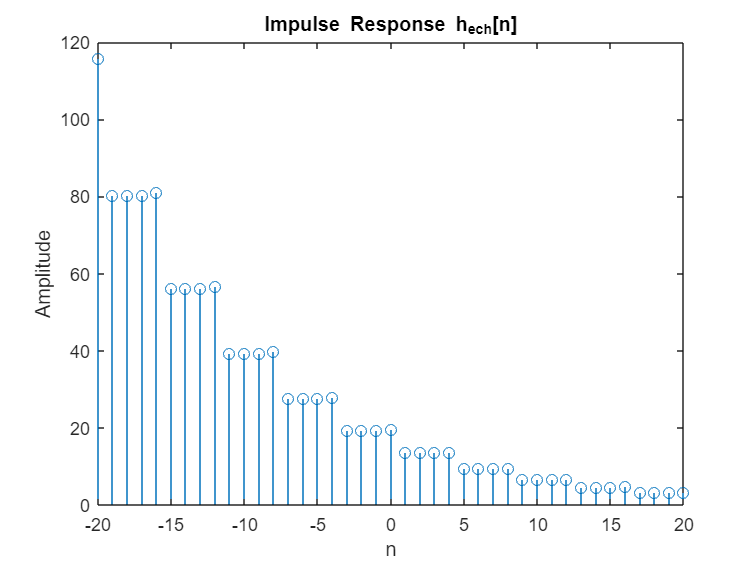

alpha = 0.7;
N = 4;
n_values = -20:20;
h_ech = zeros(size(n_values));

max_iterations = 100; 

for k = -20:20
    indices = n_values - k * N;
    valid_indices = find(indices >= min(n_values) & indices <= max(n_values));
    h_ech(valid_indices) = h_ech(valid_indices) + alpha^k;
    
    if max(valid_indices) == max(n_values)
        break;
    end
end


% Plot the impulse response
figure;
stem(n_values, h_ech);
title('Impulse Response h_{ech}[n]');
xlabel('n');
ylabel('Amplitude');

(d) Load the audiofile aclarinet.mp3 (Moodle) into your workspace using audioread and compute the convolution with the generated impulse response hech. Set N to a number of samples for one second. Play the result using the MATLAB function sound. What do you notice? After that, set the values α and N to your own desire.

Example 5: 

Sounds 

Example 6: 

Pre-Processing filter

Example 7: 

Discrete-Time Fourier Transform - Implementation